%% QUADRATIC TIME SERIES MODELING APPROACH FOR FRANCE CO2 EMISSIONS
% This script uses MATLAB's detrend() function followed by ARIMA modeling with grid search

%% SECTION 1 — Load and Prepare Data
FranceData = readtable("FranceDatawithPop.csv");

% Convert 'Year' to datetime
FranceData.Year = datetime(FranceData.Year, 1, 1);

% Convert to timetable
FranceTT = table2timetable(FranceData, "RowTimes", "Year");

% Split into training and test sets
selectedCut = datetime(2018, 1, 1);
trainData = FranceTT(FranceTT.Year < selectedCut, :);
testData  = FranceTT(FranceTT.Year >= selectedCut, :);

fprintf("✅ Height of training data: %d\n", height(trainData));

✅ Height of training data: 208


fprintf("✅ Height of test data: %d\n", height(testData));

✅ Height of test data: 6



%% SECTION 2 — Log Transform
fprintf('\n===== LOG TRANSFORMATION =====\n');


===== LOG TRANSFORMATION =====



% Log transform to stabilize variance
trainData.logTotal = log(trainData.Total + 1);
testData.logTotal = log(testData.Total + 1);

fprintf('✅ Applied log transformation\n');

✅ Applied log transformation



%% SECTION 3 — Quadratic Detrending using detrend()
fprintf('\n===== QUADRATIC DETRENDING =====\n');


===== QUADRATIC DETRENDING =====



% Remove quadratic trend from log-transformed data using detrend()
quadDetrendedTable = detrend(trainData(:,"logTotal"), 2);

% Extract the quadratic trend component
quadTrend = trainData(:,"logTotal");
quadTrend.(1) = quadTrend.(1) - quadDetrendedTable.(1);

% Store the detrended residuals
quadRemainder = quadDetrendedTable.logTotal;

fprintf('✅ Quadratic detrending complete\n');

✅ Quadratic detrending complete



%% SECTION 4 — Check Stationarity After Detrending
[h_detrend, p_detrend] = adftest(quadRemainder);

fprintf('\n===== STATIONARITY CHECK (After Quadratic Detrending) =====\n');


===== STATIONARITY CHECK (After Quadratic Detrending) =====


if h_detrend == 1
    fprintf('✅ Detrended series is STATIONARY (p=%.4f)\n', p_detrend);
else
    fprintf('⚠️  Detrended series is still NOT stationary (p=%.4f)\n', p_detrend);
end

✅ Detrended series is STATIONARY (p=0.0092)


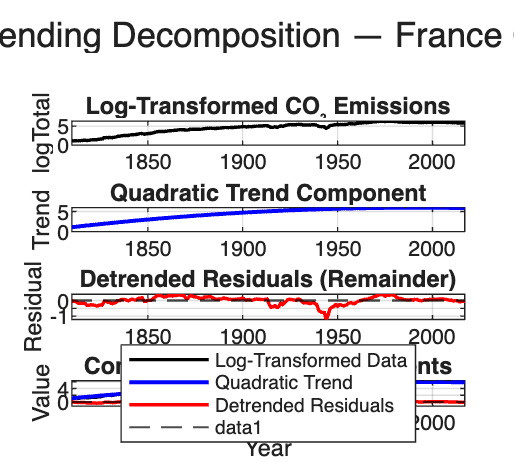


%% SECTION 5 — Visualize Decomposition
figure('Position', [100 100 1000 900]);

subplot(4,1,1);
plot(trainData.Year, trainData.logTotal, 'k-', 'LineWidth', 1.3, 'DisplayName', 'Input data');
title('Log-Transformed CO₂ Emissions');
ylabel('logTotal'); grid on;

subplot(4,1,2);
plot(trainData.Year, quadTrend.logTotal, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Trend');
title('Quadratic Trend Component');
ylabel('Trend'); grid on;

subplot(4,1,3);
plot(trainData.Year, quadRemainder, 'r-', 'LineWidth', 1.3, 'DisplayName', 'Detrended data');
hold on;
yline(0, 'k--', 'LineWidth', 1);
hold off;
title('Detrended Residuals (Remainder)');
ylabel('Residual'); grid on;

subplot(4,1,4);
plot(trainData.Year, trainData.logTotal, 'k-', 'LineWidth', 1.3, 'DisplayName', 'Log-Transformed Data');
hold on;
plot(trainData.Year, quadTrend.logTotal, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Quadratic Trend');
plot(trainData.Year, quadRemainder, 'r-', 'LineWidth', 1.3, 'DisplayName', 'Detrended Residuals');
yline(0, 'k--', 'LineWidth', 0.8);
hold off;
title('Combined View: All Components');
xlabel('Year'); ylabel('Value'); 
legend('Location', 'best'); grid on;

sgtitle('Quadratic Detrending Decomposition — France CO₂ Emissions');


%% SECTION 6 — ACF and PACF Analysis
fprintf('\n===== ACF/PACF ANALYSIS =====\n');


===== ACF/PACF ANALYSIS =====


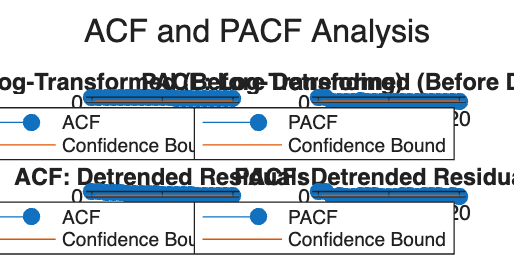


figure('Position', [100 100 1000 500]);

subplot(2,2,1);
autocorr(trainData.logTotal);
title('ACF: Log-Transformed (Before Detrending)');

subplot(2,2,2);
parcorr(trainData.logTotal);
title('PACF: Log-Transformed (Before Detrending)');

subplot(2,2,3);
autocorr(quadRemainder);
title('ACF: Detrended Residuals');

subplot(2,2,4);
parcorr(quadRemainder);
title('PACF: Detrended Residuals');

sgtitle('ACF and PACF Analysis');


fprintf('✅ Review ACF/PACF plots to identify ARIMA parameters\n');

✅ Review ACF/PACF plots to identify ARIMA parameters



%% SECTION 7 — Grid Search for Best ARIMA Parameters
fprintf('\n===== GRID SEARCH FOR ARIMA PARAMETERS =====\n');


===== GRID SEARCH FOR ARIMA PARAMETERS =====



% Define parameter ranges (expanded based on friend's approach)
ar_values = [1, 2, 3, 4, 5, 6, 7];
ma_values = [0, 1, 2, 3];

% Initialize results storage
results = [];
remainder = quadRemainder;

fprintf('Beginning grid search...\n');

Beginning grid search...



% Fit ARIMA model for each combination of AR and MA values
for ar = ar_values
    for ma = ma_values
        try
            model = arima(ar, 0, ma);
            fit = estimate(model, remainder, 'Display', 'off');

            % Get log likelihood via infer()
            [~, ~, logL] = infer(fit, remainder);

            if numel(logL) > 1
                logL = sum(logL);
            end

            % Compute AIC and BIC
            numParams = numel(fit.AR) + numel(fit.MA) + 2; % AR, MA, constant, variance
            [aic, bic] = aicbic(logL, numParams, numel(remainder));

            % Store results: ar, ma, aic, bic
            results = [results; ar, ma, aic, bic];

        catch ME
            fprintf('⚠️  Failed to fit ARIMA(%d,0,%d): %s\n', ar, ma, ME.message);
            continue;
        end
    end
end

fprintf('✅ Successfully tested %d models\n', size(results, 1));

✅ Successfully tested 28 models



%% SECTION 8 — Display Top Models
fprintf('\n===== TOP 10 MODELS BY AIC =====\n');


===== TOP 10 MODELS BY AIC =====



% Convert to table and sort by AIC
resultsTable = array2table(results, 'VariableNames', {'AR', 'MA', 'AIC', 'BIC'});
resultsTable = sortrows(resultsTable, 'AIC');

% Display top 10
fprintf('%-15s %-10s %-12s\n', 'Model', 'AIC', 'BIC');

Model           AIC        BIC         


fprintf('%s\n', repmat('-', 1, 45));

---------------------------------------------



for i = 1:min(10, height(resultsTable))
    fprintf('ARIMA(%d,0,%d)   %10.2f  %12.2f\n', ...
        resultsTable.AR(i), resultsTable.MA(i), ...
        resultsTable.AIC(i), resultsTable.BIC(i));
end

ARIMA(7,0,3)      -424.82       -384.77
ARIMA(1,0,1)      -424.52       -411.17
ARIMA(2,0,0)      -424.19       -410.84
ARIMA(3,0,2)      -424.09       -400.73
ARIMA(1,0,0)      -423.97       -413.95
ARIMA(6,0,0)      -423.52       -396.82
ARIMA(4,0,0)      -423.45       -403.42
ARIMA(1,0,2)      -423.20       -406.51
ARIMA(2,0,1)      -423.07       -406.39
ARIMA(5,0,0)      -423.02       -399.66



% Identify best model (lowest AIC)
bestAR = resultsTable.AR(1);
bestMA = resultsTable.MA(1);
fprintf('\n✅ BEST MODEL: ARIMA(%d,0,%d)\n', bestAR, bestMA);


✅ BEST MODEL: ARIMA(7,0,3)


fprintf('   AIC: %.2f | BIC: %.2f\n', resultsTable.AIC(1), resultsTable.BIC(1));

   AIC: -424.82 | BIC: -384.77



% Fit the best model
bestModel = arima(bestAR, 0, bestMA);
bestModel = estimate(bestModel, remainder, 'Display', 'off');

%% SECTION 9 — Forecast on Training Data
fprintf('\n===== FORECASTING ON TRAINING DATA =====\n');


===== FORECASTING ON TRAINING DATA =====



frcst = table;
frcst.Time = trainData.Year;
frcst.Idx = (1:height(trainData))';
frcstHorizon = height(frcst);

% Get the trend component for training period
frcst.trendComp = quadTrend.logTotal;

% Forecast ARIMA on training data
[frcst.arimaFrcst, frcst.arimaResiduals] = forecast(bestModel, frcstHorizon, remainder);

% Combine trend + ARIMA forecast
frcst.sumArima = frcst.trendComp + frcst.arimaFrcst;
frcst.totalArima = exp(frcst.sumArima) - 1;

% Calculate training RMSE
trainRMSE = sqrt(mean((frcst.totalArima - trainData.Total).^2));
fprintf('Training RMSE: %.4f\n', trainRMSE);

Training RMSE: 51.5898


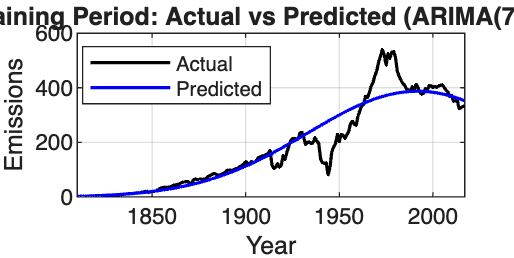


% Plot training fit
figure('Position', [100 100 1000 500]);
plot(trainData.Year, trainData.Total, 'k-', 'LineWidth', 1.2, 'DisplayName', 'Actual');
hold on;
plot(frcst.Time, frcst.totalArima, 'b-', 'LineWidth', 1.2, 'DisplayName', 'Predicted');
xlabel('Year'); ylabel('Emissions');
title(sprintf('Training Period: Actual vs Predicted (ARIMA(%d,0,%d))', bestAR, bestMA));
legend('Location', 'best'); grid on;
hold off;


%% SECTION 10 — Forecast on Test Data
fprintf('\n===== FORECASTING ON TEST DATA =====\n');


===== FORECASTING ON TEST DATA =====



% Create forecast table for test period
frcstTest = table;
frcstTest.Time = testData.Year;
frcstTest.Idx = (height(trainData)+1 : height(trainData)+height(testData))';
frcstHorizonTest = height(frcstTest);

% We need to extrapolate the quadratic trend to test period
% Fit polynomial to get coefficients
t_train = (1:height(trainData))';
p_coeffs = polyfit(t_train, quadTrend.logTotal, 2);

% Evaluate trend at test indices
trendTestLog = polyval(p_coeffs, frcstTest.Idx);
frcstTest.trendComp = trendTestLog;

% Forecast ARIMA for test period
[frcstTest.arimaFrcst, frcstTest.arimaResiduals] = forecast(bestModel, frcstHorizonTest, remainder);

% Combine trend + ARIMA forecast
frcstTest.sumArima = frcstTest.trendComp + frcstTest.arimaFrcst;
frcstTest.totalArima = exp(frcstTest.sumArima) - 1;

% Calculate test RMSE (with and without 2020)
testYears = year(testData.Year);
exclude2020 = testYears ~= 2020;

testRMSE_with2020 = sqrt(mean((frcstTest.totalArima - testData.Total).^2));
testRMSE_no2020 = sqrt(mean((frcstTest.totalArima(exclude2020) - testData.Total(exclude2020)).^2));

fprintf('Test RMSE (with 2020):    %.4f\n', testRMSE_with2020);

Test RMSE (with 2020):    36.7563


fprintf('Test RMSE (without 2020): %.4f\n', testRMSE_no2020);

Test RMSE (without 2020): 32.6675


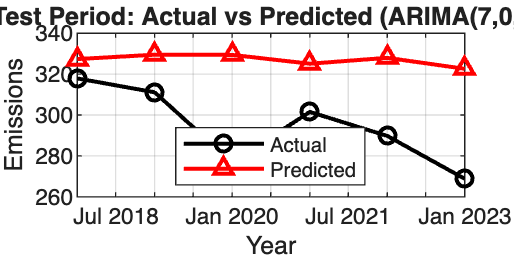


% Plot test forecast
figure('Position', [100 100 1000 500]);
plot(testData.Year, testData.Total, 'ko-', 'LineWidth', 1.5, 'DisplayName', 'Actual');
hold on;
plot(frcstTest.Time, frcstTest.totalArima, 'r^-', 'LineWidth', 1.5, 'DisplayName', 'Predicted');
xlabel('Year'); ylabel('Emissions'); grid on;
title(sprintf('Test Period: Actual vs Predicted (ARIMA(%d,0,%d))', bestAR, bestMA));
legend('Location', 'best');
hold off;

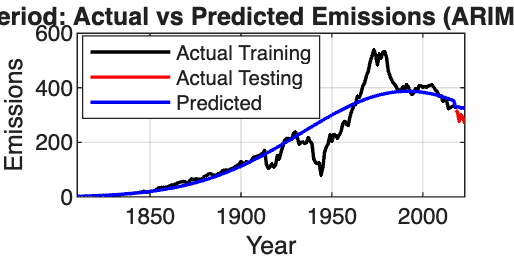


%% SECTION 11 — Combined Visualization
figure('Position', [100 100 1200 600]);

% Combine training and test data
combinedActualTime = [trainData.Year; testData.Year];
combinedActualTotal = [trainData.Total; testData.Total];
combinedPredictedTime = [frcst.Time; frcstTest.Time];
combinedPredictedTotal = [frcst.totalArima; frcstTest.totalArima];

plot(trainData.Year, trainData.Total, 'k-', 'LineWidth', 1.3, 'DisplayName', 'Actual Training');
hold on;
plot(testData.Year, testData.Total, 'r-', 'LineWidth', 1.3, 'DisplayName', 'Actual Testing');
plot(combinedPredictedTime, combinedPredictedTotal, 'b-', 'LineWidth', 1.3, 'DisplayName', 'Predicted');
xlabel('Year'); ylabel('Emissions');
title(sprintf('Full Period: Actual vs Predicted Emissions (ARIMA(%d,0,%d))', bestAR, bestMA));
legend('Location', 'best'); grid on;
hold off;


%% SECTION 12 — Residual Diagnostics for Best Model
fprintf('\n===== RESIDUAL DIAGNOSTICS =====\n');


===== RESIDUAL DIAGNOSTICS =====


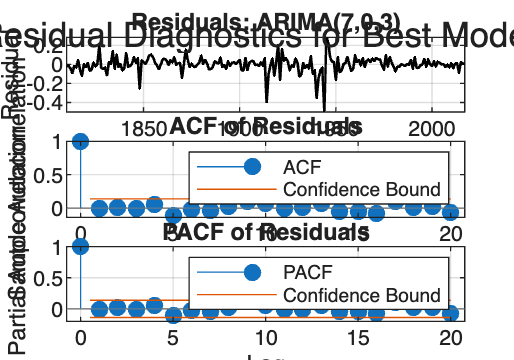


resBest = infer(bestModel, remainder);

figure('Position', [100 100 1000 700]);

subplot(3,1,1);
plot(trainData.Year(end-length(resBest)+1:end), resBest, 'k-', 'LineWidth', 1);
title(sprintf('Residuals: ARIMA(%d,0,%d)', bestAR, bestMA));
ylabel('Residual'); grid on;

subplot(3,1,2);
autocorr(resBest);
title('ACF of Residuals');

subplot(3,1,3);
parcorr(resBest);
title('PACF of Residuals');

sgtitle('Residual Diagnostics for Best Model');

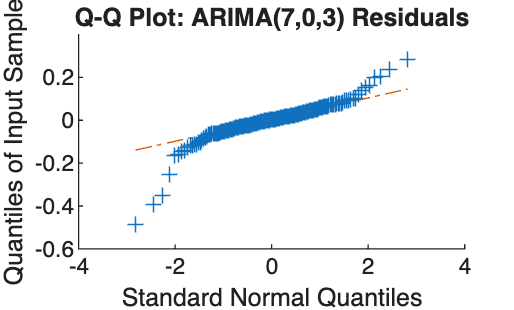


% Q-Q plot
figure;
qqplot(resBest);
titleText = sprintf('Q-Q Plot: ARIMA(%d,0,%d) Residuals', bestAR, bestMA);
title(titleText);


fprintf('\n✅ Analysis complete!\n');


✅ Analysis complete!



%% SECTION 13 — Summary Statistics
fprintf('\n===== FINAL SUMMARY =====\n');


===== FINAL SUMMARY =====


fprintf('Best Model: ARIMA(%d,0,%d)\n', bestAR, bestMA);

Best Model: ARIMA(7,0,3)


fprintf('Training RMSE:             %.4f\n', trainRMSE);

Training RMSE:             51.5898


fprintf('Test RMSE (with 2020):     %.4f\n', testRMSE_with2020);

Test RMSE (with 2020):     36.7563


fprintf('Test RMSE (without 2020):  %.4f\n', testRMSE_no2020);

Test RMSE (without 2020):  32.6675



%% Save results
save('QuadraticModel_Results.mat', 'bestModel', 'resultsTable', ...
     'trainData', 'testData', 'quadRemainder', 'quadTrend', 'frcst', 'frcstTest');
fprintf('✅ Results saved to QuadraticModel_Results.mat\n');

✅ Results saved to QuadraticModel_Results.mat
